# Train Short Time Fourier Transform

*Michael Caiola (Michael.Caiola@fda.hhs.gov) and Meijun Ye (Meijun.Ye@fda.hhs.gov)*

Live script used to train the Short time fourier transform network

tic
fs = 100;
fol = "D:\3minSept22";
ds_all=ResampleDatastore(fol,fs,'DataAugmentation',false);
ds_test = ResampleDatastore(fol,fs,'TestSet',false);
ds90_all=ResampleDatastore(fol,fs,'DataAugmentation',true);
ds90_test = ResampleDatastore(fol,fs,'TestSet',true);
toc

Used Matched Age and Gender subjects/sessions of HEA and STR

# HEA subjects/sessions: 595/629
# STR subjects/sessions: 527/585
# TBI subjects/sessions: 552/629


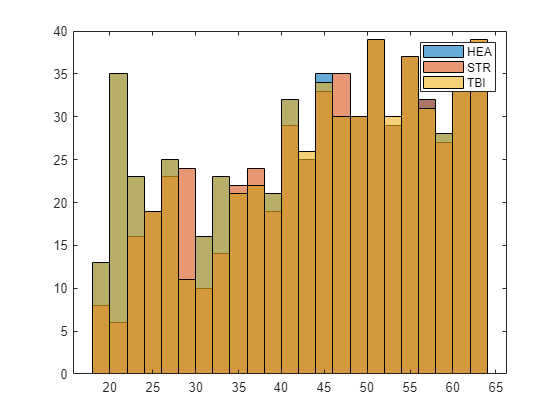

[HEA,STR,TBI] = MatchSubjects();

s = split(HEA.Location,'\');
s = string(s(:,9));
s = split(s,'.');
HEA = s(:,1);
s = split(STR.Location,'\');
s = string(s(:,9));
s = split(s,'.');
STR = s(:,1);
s = split(TBI.Location,'\');
s = string(s(:,9));
s = split(s,'.');
TBI = s(:,1);

Check for overlaps

f = string(ds_all.Datastore.Files);
in_HEA = [];
in_STR = [];
in_TBI = [];
for i = 1:length(f)
    for j = 1:length(HEA)
        if contains(f(i),HEA(j))
            in_HEA = [in_HEA i];
            break
        end
    end
    for j = 1:length(STR)
        if contains(f(i),STR(j))
            in_STR = [in_STR i];
            break
        end
    end
    for j = 1:length(TBI)
        if contains(f(i),TBI(j))
            in_TBI = [in_TBI i];
            break
        end
    end
end
%in_TBI = find(ds_all.Labels == "TBI")';
in = [in_HEA, in_STR, in_TBI];
ds_match = subset(ds_all,in);
ds_match_test = subset(ds_test,in);
ds90_match = subset(ds90_all,in);
ds90_match_test = subset(ds90_test,in);

Set aside >=50 patients for IV

c = string(categories(ds_match.Labels));
numsub = max(50,floor(min(countcats(ds_match.Labels))*.2));
disp("Using " + numsub + " for IV.")

Using 582 for IV.


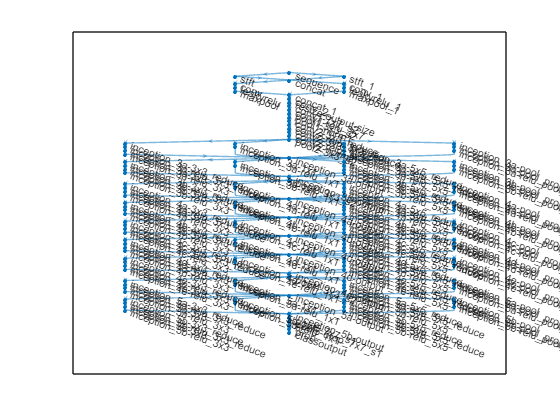

in_iv = [];
in_cv = [];
for i = 1:length(c)
    in = find(ds_match.Labels == c(i));
    r = randperm(length(in));
    in_iv = [in_iv; in(r(1:numsub))];
    in_cv = [in_cv; in(r(numsub+1:end))];
end
X_Train=subset(ds_match,in_cv);
X_Test=subset(ds_match_test,in_iv);
Y_Train=subset(ds90_match,in_cv);
Y_Test=subset(ds90_match_test,in_iv);
save("STFTData.mat","X_Train","X_Test","Y_Train","Y_Test")

Run Network

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:09 |       29.17% |       33.31% |      16.1284 |      15.9765 |      1.0000e-04 |
|       1 |          50 |       00:02:20 |       54.17% |              |       2.7504 |              |      1.0000e-04 |
|       1 |         100 |       00:04:21 |       50.00% |       45.67% |       1.1569 |       1.6274 |      1.0000e-04 |
|       1 |         150 |       00:05:35 |       41.67% |              |       1.7076 |              |      1.0000e-04 |
|       1 |         200 |       

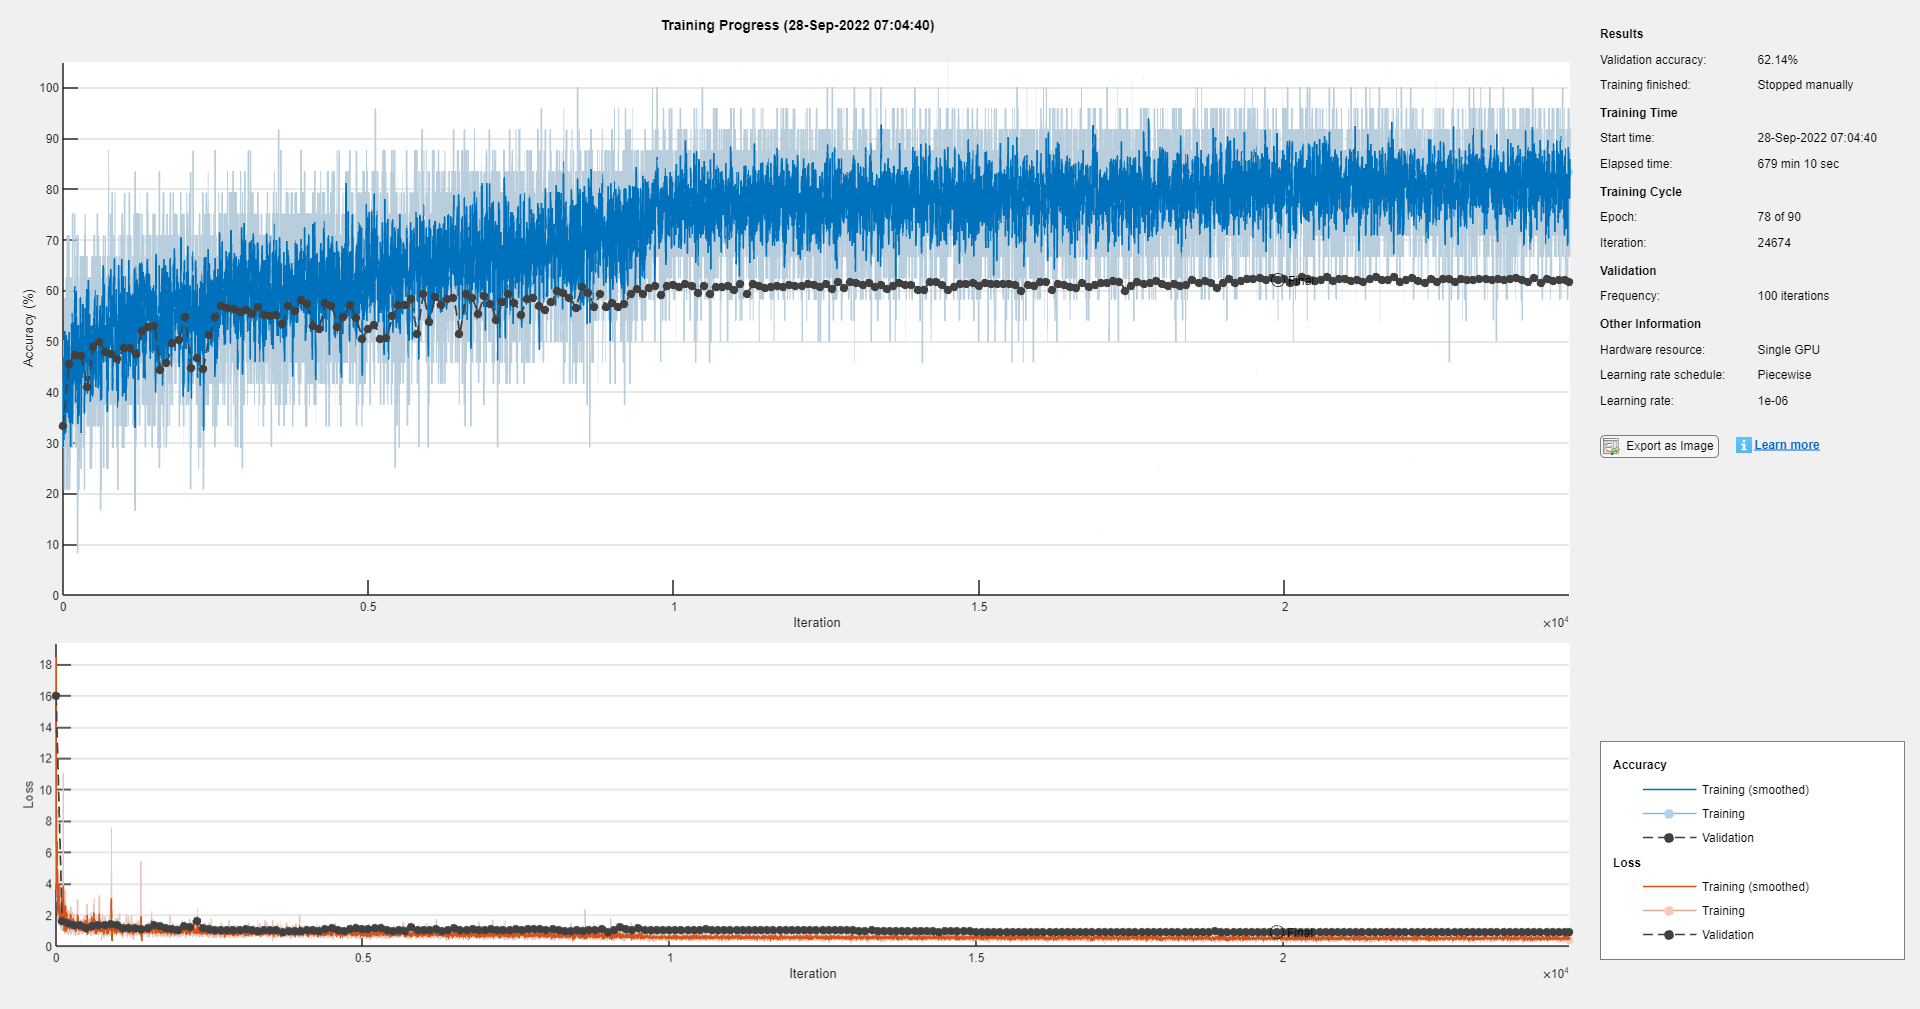

% gpuDevice(1);
% %load("STFTLayers.mat")
% reset(X_Train);
% reset(X_Test);
% miniBatchSize=24;
% X_Train.MiniBatchSize=miniBatchSize;
% X_Test.MiniBatchSize=miniBatchSize;
% opts=trainingOptions("adam","Plots","training-progress","ExecutionEnvironment","gpu", ...
%     "Shuffle","every-epoch","MiniBatchSize",miniBatchSize,"MaxEpochs",30*3,...
%     "InitialLearnRate",.0001,"LearnRateSchedule","piecewise","LearnRateDropPeriod",30,"GradientThreshold",10,...
%     "OutputNetwork","best-validation-loss","ValidationData",X_Test,"ValidationFrequency",100);
% net=trainNetwork(X_Train,lgraph_2,opts);

## CNN Models

### Layers:

3 types of convolution 

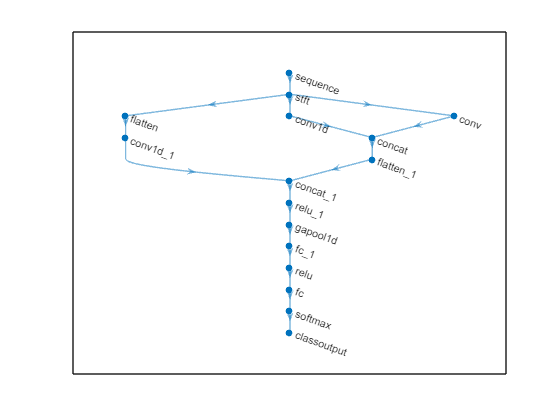

load("STFTNet.mat","lgraph_2");
plot(lgraph_2)

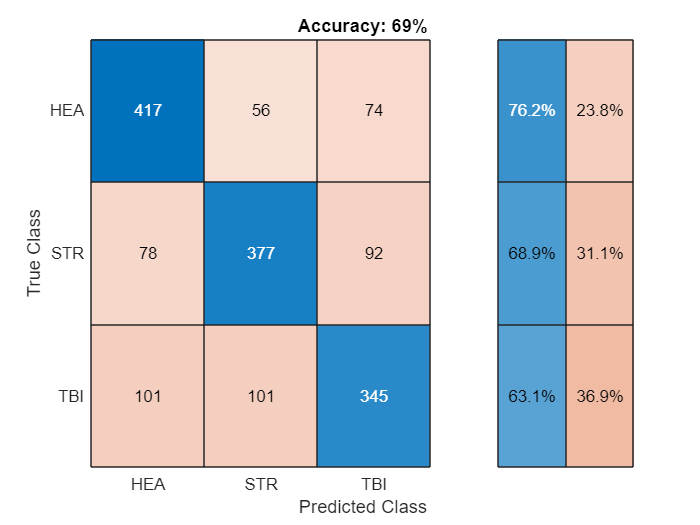

load("STFTNet.mat")
Snet4 = MdlResults(net4a,Y_Test,Y_Test.Labels);
classify(Snet4);

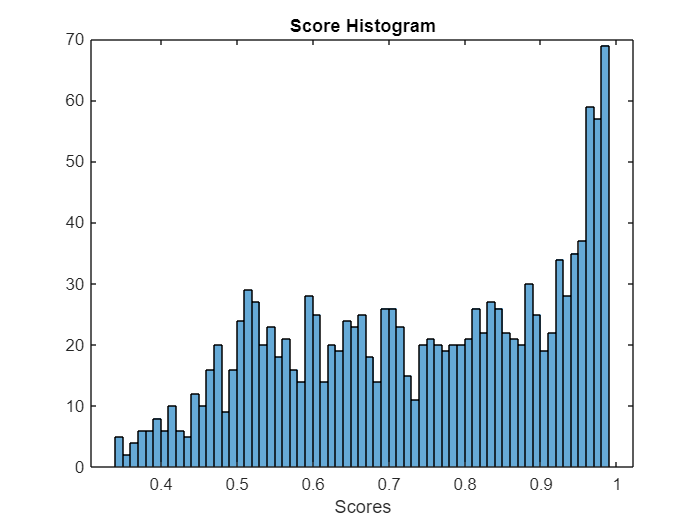

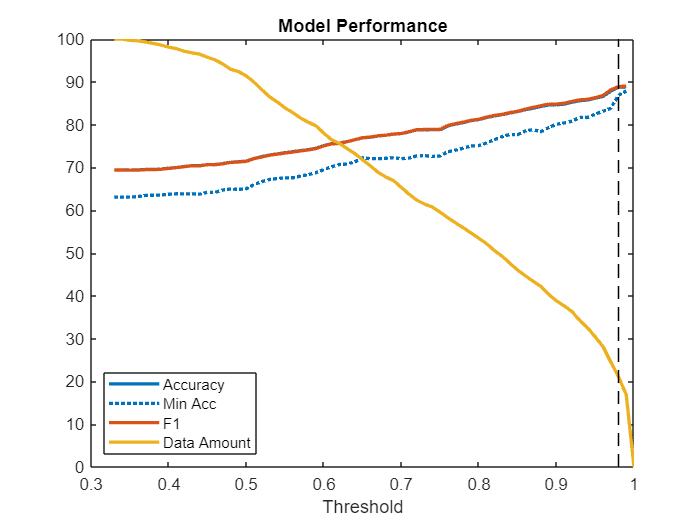

Data Remaining: 0.21085


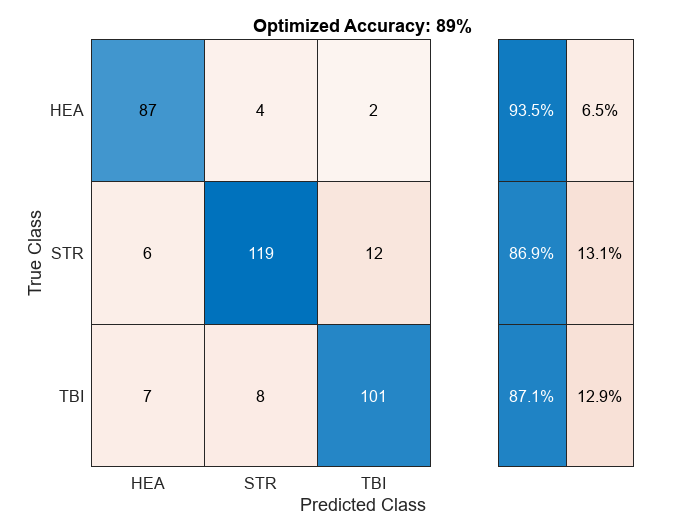

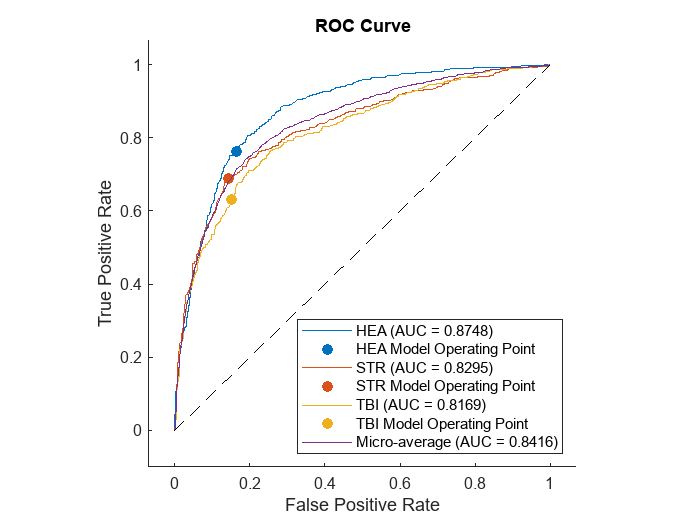

metrics(Snet4);

## **Disclaimer**

This software and documentation (the "Software") were developed at the Food and Drug Administration (FDA) by employees of the Federal Government in the course of their official duties. Pursuant to Title 17, Section 105 of the United States Code, this work is not subject to copyright protection and is in the public domain. Permission is hereby granted, free of charge, to any person obtaining a copy of the Software, to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, or sell copies of the Software or derivatives, and to permit persons to whom the Software is furnished to do so. FDA assumes no responsibility whatsoever for use by other parties of the Software, its source code, documentation or compiled executables, and makes no guarantees, expressed or implied, about its quality, reliability, or any other characteristic. Further, use of this code in no way implies endorsement by the FDA or confers any advantage in regulatory decisions. Although this software can be redistributed and/or modified freely, we ask that any derivative works bear some notice that they are derived from it, and any modified versions bear some notice that they have been modified. The Software is not intended to make clinical diagnoses or to be used in any way to diagnose or treat subjects for whom the EEG is taken.